
clear
SetRNG(11);
format shortG
warning off;
load fisheriris
inputs_ori = [
    2 2;
    2 -2;
    -2 -2;];
inputs = inputs_ori-mean(inputs_ori);

inputs_ori = [
    3 3;
    3 -1;
    -3 1;
    -3 -3;
    1 1;
    -1 -1];
inputs = inputs_ori-mean(inputs_ori);
% inputs_ori = meas(:,1:4);% data 1
% inputs = inputs_ori-mean(inputs_ori);
% inputs_ori = readtable('syn_2.csv');% data 6
% inputs_ori = inputs_ori(500:1000,1:end-1);
% inputs_ori = table2array(inputs_ori);
% inputs_ori = str2double(inputs_ori);
% inputs = inputs_ori-mean(inputs_ori);

%test if the mean less than 90

x = linspace(-5,5,1000);
y = 4*x+50*rand(1,1000);
inputs_ori = [x;y];
inputs_ori = inputs_ori';

inputs_ori = [
    2 2;
    1 0;
    -2 -2;
    -1 0;];
inputs_ori = 5*rand(500,2);
inputs = inputs_ori-mean(inputs_ori);



% v = [];
% for i = 1:1000;
%     v = [v;sign(2*rand(size(inputs,1),1)-1)'];
% end
% v = unique(v,'rows');
% s = 0;
% for i = 1:size(v,1);
%     di = v(i,:);
%     new_input = di'.*inputs;
%     if sum(new_input*mean(new_input)'>0) == size(inputs,1);
%         s = s+1;
%         %new_input
%     end
% end
% s/2

ans =      0


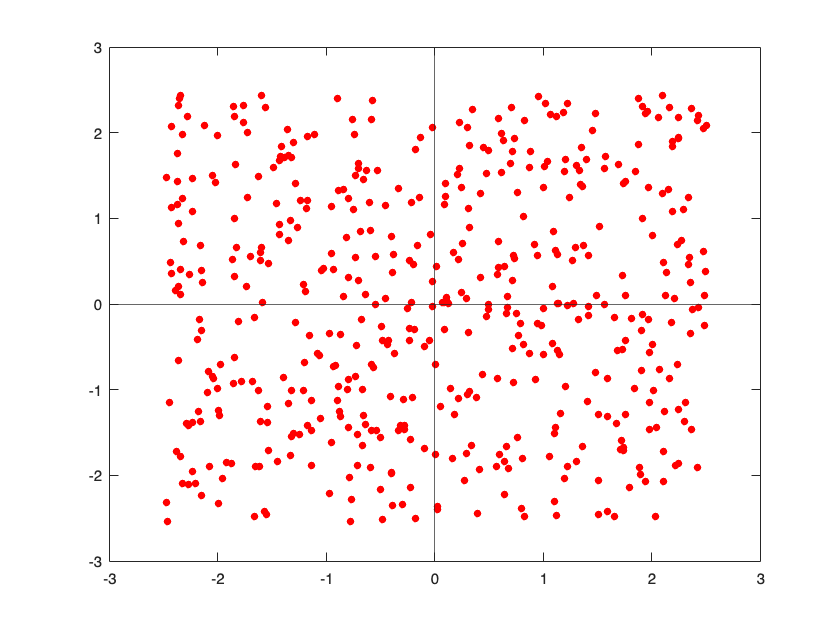



plot(inputs(1:end,1),inputs(1:end,2),'r.','MarkerSize',15)
xline(0);
yline(0);

% inputs_ori = meas(:,1:4);% data 1
% inputs = inputs_ori-mean(inputs_ori);
%inputs = normr(inputs);
[coeff_real,~,~,~,explained_1,~] = pca(inputs);

%SetRNG(1);
dim = size(inputs,2);
n_src = dim;
n_dst = 500;
n_per_src = 2;
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
 cells = synaptic_weights_mat; %original
% cells = [-2;0];
% cells = [0;-2];
epoch = 500;
ori_cycle1_cells = cells;
final_weight = [];

sum1 = [];
test1 = [];
mean1 = [];
for e = 1:epoch;
    imterim_weight = [];
    sampled_data = inputs;
    sampled_data = inputs(randperm(size(inputs, 1)),:);
    mean_sum = [];
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        input1 = input1_ori';
        product = input1'*ori_cycle1_cells;
        signs = sign(product);
        sign2 = sign(input1'*ori_cycle1_cells(:,1));
        sum1 = [sum1;sum(signs)];
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        mean_sum = [mean_sum,sign2.*input1];
        update_winner_norm = update_winner_ori;
        ori_cycle1_cells(:,winning_idx) = update_winner_norm;
    end
    mean1 = [mean1,normc(mean(mean_sum,2))];
end

normc(update_winner_norm(:,end))

ans =       0.99215
      0.12508


normc(mean(mean_sum,2))

ans =      0.015984
     -0.99987


normc(coeff_real)

ans =       0.87735     -0.47985
      0.47985      0.87735



bench_v = ones(size(update_winner_norm,1),1);
id = find(sign(bench_v'*normc(update_winner_norm)) == 1)';
[max_align,id] = max(abs(normc(update_winner_norm)'*coeff_real(:,1)));
center1 = normc(mean(update_winner_norm(:,id),2));
%center1 = normc(update_winner_norm(:,end-1)+update_winner_norm(:,end-2));
% ori_acute = sum(sign(triu(inputs*inputs')),'all')
% after_acute = sum(sign(triu(mean_sum'*mean_sum)),'all')
% 
% 
w_to_PC = normc(center1)'*normc(coeff_real)

w_to_PC =      -0.94924     -0.31454


% mean_to_PC = normc(mean(mean_sum,2))'*normc(coeff_real)
% w_to_mean = normc(center1)'*normc(mean(mean_sum,2))
% 
ori_line_to_mean = sum(sign(mean1(:,end)'*inputs') == 1)./size(inputs,1)

ori_line_to_mean =         0.502


after_line_to_mean = sum(sign(mean1(:,end)'*mean_sum) == 1)./size(inputs,1)

after_line_to_mean =      1


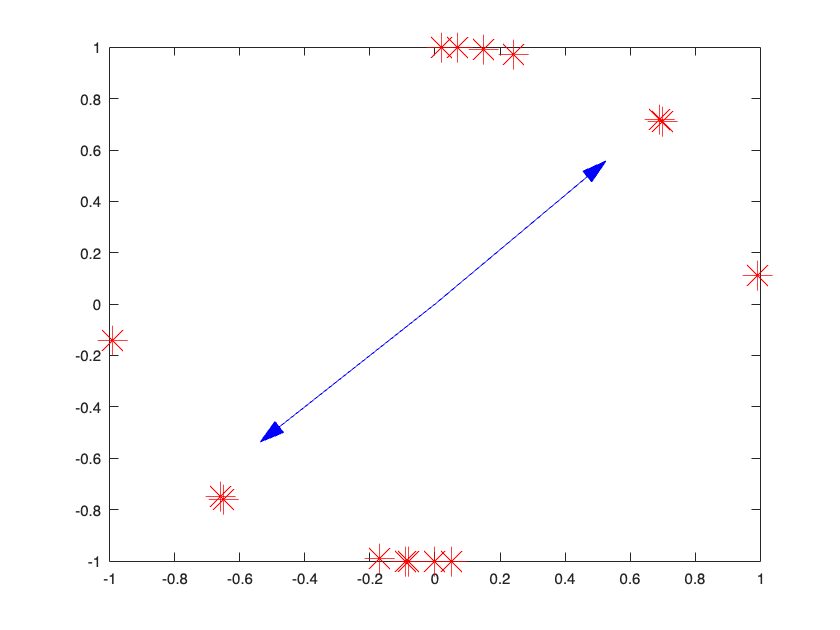

max(abs(normc(update_winner_norm)'*coeff_real(:,1)));
new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
new_weight = round(new_weight,2);


% figure;
% plot(new_weight(1:end,1),new_weight(1:end,2),'r*','MarkerSize',20)
% xlim([-1 1])
% ylim([-1 1])
% zlim([-1 1])


[idx,C,sumd,D] = kmeans(new_weight,2);

o = [0 0];
figure;
view(3)
plot(new_weight(1:end,1),new_weight(1:end,2),'r*','MarkerSize',20)
% arrow(o,C(end-6,:),'Color','b');
%arrow(o,C(end-5,:),'Color','b');
%arrow(o,C(end-4,:),'Color','b');
% arrow(o,C(end-3,:),'Color','b');
% arrow(o,C(end-2,:),'Color','b');
arrow(o,C(end-1,:),'Color','b');
arrow(o,C(end,:),'Color','b');
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])


center2 = normr(C)';
center2'*normc(coeff_real)

ans =      -0.95976     -0.28083
      0.95097      0.30928


%normc(center2(:,2)+center2(:,4))'*normc(coeff_real)